%This code generates the chirp signal

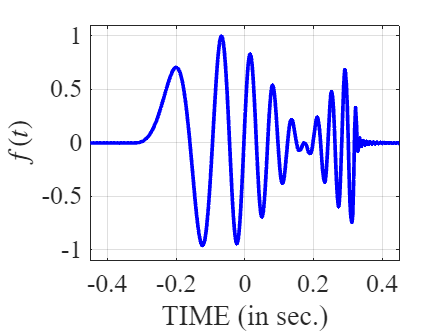


%% Parameters

F0 = 100;                 % Hz
Ts = 1/(2*F0);            % 0.005 s
M  = 130;

Tmax = 0.45;

%% Time vector

Fs_plot = 1e5;
td = -Tmax : 1/Fs_plot : Tmax;

%% Coefficients

m = 1:M;

cm = sin(2*pi*0.005*m) .* ...
     sin(2*pi*0.081*(m.^2.1)/(2*M));

%% Center the sinc train

shift = M*Ts/2;           % = 0.325 s

%% Generate signal

fd = zeros(size(td));

for k = 1:M

    center = k*Ts - Ts/2 - shift;

    fd = fd + cm(k)*sinc(2*F0*(td-center));

end

%% Normalize

fd = fd/max(abs(fd));

%% Save

save('chirp.mat','fd','td');

%% Plot

figure('Color','w');

plot(td,fd,'b','LineWidth',2);

xlabel('TIME (in sec.)', ...
    'FontSize',16, ...
    'FontName','Times');

ylabel('$f(t)$', ...
    'Interpreter','latex', ...
    'FontSize',16);

grid on;
box on;

xlim([-0.45 0.45]);
ylim([-1.1 1.1]);

set(gca,...
    'FontSize',14,...
    'FontName','Times');


disp('Signal saved to trial.mat');

Signal saved to trial.mat
